# Lab work B

clear all;
clc;
close all;

lab_work_B_init_routine;

% u1 spoiler angle  [deg/10]
% u2 forward acceleration [ms^-2]
% u3 elevator angle [deg]

% x1 relative altitude [m]
% x2 forward speed [ms^-1]
% x3 pitch angle [deg]
% x4 pitch rate [degs^-1]
% x5 vertical speed [ms^-1]

% y1 relative altitude [m]
% y2 forward speed [ms^-1]
% y3 pitch angle [deg]

A =[0 0 1.1320 0 -1; 0 -0.0538 -0.1712 0 0.0705; 0 0 0 1 0; 0 0.0485 0 -0.8556 -1.0130; 0 -0.2909 0 1.0532 -0.6859];
B = [0 0 0; -0.1200 1 0; 0 0 0; 4.4190 0 -1.665; 1.575 0 -0.0732];
C = [1 0 0 0 0; 0 1 0 0 0; 0 0 1 0 0];
D =[0 0 0; 0 0 0; 0 0 0];

% the bandwidth for the closed loop system should be 10 rad s^-1
% zero steady state error

k1=1;
k3=1;
tau_1=[0.5 1.2];
k_2=[0.9 1.1];
tau_2=[0.5 2.5];
zeta=[0.9 1];
tau_3=[1 1.8];

%nominal system
s=tf('s');
Gu1_n=k1/(mean(tau_1)*s+1);
Gu2_n = mean(k_2);
% Gu2_n=mean(k_2)/(mean(tau_2)^2*s^2+2*mean(zeta)*mean(tau_2)*s+1);
Gu3_n=k3/(mean(tau_3)*s+1);

G=tf(ss(A,B,C,D));
Grga=G

Grga =
 
  From input 1 to output...
            -1.575 s^3 - 1.119 s^2 + 1.541 s - 0.08159
   1:  ----------------------------------------------------
       s^5 + 1.595 s^4 + 1.757 s^3 + 0.1112 s^2 + 0.05614 s
 
         -0.12 s^3 - 0.07394 s^2 - 0.5319 s - 0.2458
   2:  ------------------------------------------------
       s^4 + 1.595 s^3 + 1.757 s^2 + 0.1112 s + 0.05614
 
                 4.419 s^2 + 1.667 s + 0.1339
   3:  ------------------------------------------------
       s^4 + 1.595 s^3 + 1.757 s^2 + 0.1112 s + 0.05614
 
  From input 2 to output...
                  0.2909 s^2 + 0.2527 s + 0.3712
   1:  ----------------------------------------------------
       s^5 + 1.595 s^4 + 1.757 s^3 + 0.1112 s^2 + 0.05614 s
 
                  s^3 + 1.541 s^2 + 1.654 s
   2:  ------------------------------------------------
       s^4 + 1.595 s^3 + 1.757 s^2 + 0.1112 s + 0.05614
 
                      0.0485 s + 0.3279
   3:  ------------------------------------------------
      

s=tf('s');
Grga(1,1)=Grga(1,1)*s;
Grga(1,2)=Grga(1,2)*s;
Grga(1,3)=Grga(1,3)*s;
Grga=minreal(Grga); 

% Grga stands for "G that I use to calculate the RGA", that is, the G that
% I also use to calculate the 

G0=dcgain(Grga);
RGA=G0.*inv(G0)'

RGA =     0.6750    0.0976    0.2274
   -0.9290         0    1.9290
    1.2540    0.9024   -1.1564


%possible pairing u1-->y1, u3-->y2, u2-->y3
G10=evalfr(Grga,10); 
DRGA=G10.*inv(G10)'

DRGA =     1.0944   -0.0023   -0.0920
   -0.0024    1.0023    0.0001
   -0.0920   -0.0000    1.0920


%use u1 for y1
%use u2 for y2
%use u3 for y3
%best solution is the one provided for RGA matrix (taking into account
%that we could change the frequency if necessary)

Index

Grga=minreal(ss(Grga));

8 states removed.


NI=ni(Grga) %value okay 

NI = 1.7048e+15

% using the premade function useless calculation
% Wc=gram(Grga,'c');
% 
% Wo=gram(Grga,'o');

% !!! Be careful Alessandra, because if you use PM = PM(...) you are "deleting"
% the function PM, because it is transformed in a matrix. You should use
% like PM_Grga = PM(...) [maybe a more sensible name is better, but they dont come to mind]!!!
PM_index = PM(Grga) %partecipating matrix

PM_index =     0.1367    0.1906    0.0709
    0.0942    0.1272    0.0490
    0.1148    0.1574    0.0591


HIIA_index = HIIA(Grga) %hankel index

HIIA_index =     0.1202    0.1546    0.0885
    0.1087    0.1159    0.0784
    0.1117    0.1403    0.0817


H2=HIIA(Grga,2) % h2 norm index

H2 =     0.1239    0.1434    0.0877
    0.1028    0.1187    0.0729
    0.1342    0.1291    0.0873


%solution1(RGA) 0.3259
%solution2(DRGA) 0.3299 %slihghly better not fully better
% results suck, heading for IMC directly

## IMC controller

%Gtot = [Gu1_n 0 0; 0 Gu2_n 0; 0 0 Gu3_n];
Gtot = [Gu1_n 0 0; 0 Gu2_n 0; 0 0 Gu3_n];
Gtot = minreal(G*Gtot);


% finding the zero
zero_sys_Gtot = tzero(Gtot) %no positive zero --> for designing Q we use Gtot

zero_sys_Gtot =   -1.1765 + 0.0000i
  -0.7143 + 0.0000i
  -1.1765 + 0.0000i
  -0.7143 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.7801 + 1.0296i
  -0.7801 - 1.0296i
  -0.7801 + 1.0296i
  -0.7801 - 1.0296i


%Gtot_no_pz = remove_pz(Gtot); %NB: zeros single function DIFFER from zeros entire system
%zero_sys_Gtot_no_pz=tzero(Gtot_no_pz)
lambda=10; %chosen randomly and tuned afterwords
% >1 undershoot 
% <1 kick in the beginning 

%Q = G^(-1)*[1/(lambda*s+1)^(2) 0 0; 0 1/(lambda*s+1)^(2) 0; 0 0 1/(lambda*s+1)^(2)];
Q = Gtot^(-1)*[1/(lambda*s+1)^(3) 0 0; 0 1/(lambda*s+1)^(3) 0; 0 0 1/(lambda*s+1)^(3)]; %n=4 because to make it proper
Q  = minreal(Q);
% to be discussed 
% l11=1;
% l12=0;
% l13=0;
% 
% l21=0;
% l22=1;
% l23=0;
% 
% l31=0;
% l32=0;
% l33=1;
%Q_lambda = [(l11*s+1)^-5 l12 l13 ; l21 (l22*s+1)^-4 l23; l31 l32 (l33*s+1)^-4];
%Q_lambda = minreal(ss(Q_lambda))

%Q=inv(Gtot_no_pz)*Q_lambda;
%Q=ss(Q)
%Q=minreal(Q)

%useless
%count_p=cellfun(@(x) numel(x), p_n)
%count_z=cellfun(@(x) numel(x), z)
%n=count_p-count_z

% det=Gtot_no_pz(1,1)*(Gtot_no_pz(2,2)*Gtot_no_pz(3,3)-Gtot_no_pz(2,3)*Gtot_no_pz(3,2))...
% -Gtot_no_pz(1,2)*(Gtot_no_pz(2,1)*Gtot_no_pz(3,3)-Gtot_no_pz(2,3)*Gtot_no_pz(3,1))...
% +Gtot_no_pz(1,3)*(Gtot_no_pz(2,1)*Gtot_no_pz(3,2)-Gtot_no_pz(2,2)*Gtot_no_pz(3,1));
%det=minreal(det)

%%% example .pdf inserted in Reference
% G11=2.6/(62*s+1);
% G12=1.5/(1462*s^2+85*s+1);
% G21=1.4/(2700*s^2+120*s+1)
% G22=2.8/(90*s+1);
% Gm=[G11 G12; G21 G22]
% inv(Gm)*(1/(s+1)^1)

## **Optimal controller**

% lab_work_B_optimal_controller

## Robustness analysis

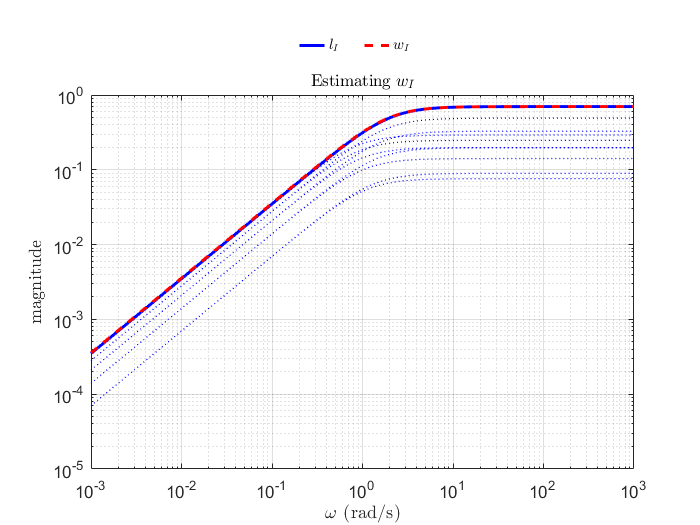

% k1=1;
% k3=1;
% tau_1=[0.5 1.2];
% k_2=[0.9 1.1];
% tau_2=[0.5 2.5];
% zeta=[0.9 1];
% tau_3=[1 1.8];
% figure();

% Gu1_n=k1/(mean(tau_1)*s+1);
% Gu2_n=mean(k_2)/(mean(tau_2)^2*s^2+2*mean(zeta)*mean(tau_2)*s+1);
% Gu3_n=k3/(mean(tau_3)*s+1);

w=logspace(-3,3,200);

% *** Gu1 ***
lI=zeros(size(w'));
Gu1_n_w =squeeze(freqresp(Gu1_n,w));

figure()
leg_entries = '';
for tau_1_0=tau_1(1):diff(tau_1)/10:tau_1(2)
    Gu1_0=k1/(tau_1_0*s+1);
    Gu1_0_w=squeeze(freqresp(Gu1_0,w));
    q=abs((Gu1_0_w-Gu1_n_w)./Gu1_n_w);
    lI=max(lI,q);
    loglog(w,q,':b','LineWidth',0.75);
    hold on
    leg_entries = [leg_entries '|'];
end
loglog(w,lI,'b');
leg_entries = [leg_entries '$l_I$|'];

wI_u1=0.357*s/(0.357*s/0.7+1);   % Values got by the plot of lI

wI_u1_w=squeeze(freqresp(wI_u1,w));
loglog(w,abs(wI_u1_w),'r--');
leg_entries = [leg_entries '$w_I$'];

auto_plot('Estimating $w_I$',...
        leg_entries,'$\omega$ (rad/s)|magnitude');

saveas(gcf,'Plots/estimation_wI_u1.m')

% *** Gu2 ***
lI=zeros(size(w'));
% Gu2_n_w =squeeze(freqresp(Gu2_n,w));
Gu2_n_w = Gu2_n;

figure()
leg_entries = '';
for k_2_0=k_2(1):diff(k_2)/4:k_2(2)
    for tau_2_0=tau_2(1):diff(tau_2)/4:tau_2(2)
        for zeta_0=zeta(1):diff(zeta)/4:zeta(2)
            Gu2_0=k_2_0/(tau_2_0^2*s^2+2*zeta_0*tau_2_0*s+1);

            Gu2_0_w=squeeze(freqresp(Gu2_0,w));
            q=abs((Gu2_0_w-Gu2_n_w)./Gu2_n_w);
            lI=max(lI,q);
            loglog(w,q,':b','LineWidth',0.75);
            hold on
            leg_entries = [leg_entries '|'];
        end
    end
end
loglog(w,lI,'b');
leg_entries = [leg_entries '$l_I$|'];

wI_u2=(1/0.15*s+0.1)/(1/0.15*s/1.5+1);   % Values got by the plot of lI

%0.15 stands for the crossover frequency tau=1/0.2
%1.5 stands for r_infinity which is the gain at w-->infinity
%0.1 stands for r_0 is the gain at zero frequency

wI_u2_w=squeeze(freqresp(wI_u2,w));
loglog(w,abs(wI_u2_w),'r--');
leg_entries = [leg_entries '$w_I$'];

auto_plot('Estimating $w_I$',...
        leg_entries,'$\omega$ (rad/s)|magnitude');

saveas(gcf,'Plots/estimation_wI_u2.m')

% *** Gu3 ***
for tau_3_0=tau_3(1):diff(tau_3)/10:tau_3(2)
    Gu3_0=k3/(tau_3_0*s+1);
end

% *** Gu2 ***
lI=zeros(size(w'));
Gu3_n_w =squeeze(freqresp(Gu3_n,w));

figure()
leg_entries = '';
for tau_3_0=tau_3(1):diff(tau_3)/10:tau_3(2)
    Gu3_0=k3/(tau_3_0*s+1);

    Gu3_0_w=squeeze(freqresp(Gu3_0,w));
    q=abs((Gu3_0_w-Gu3_n_w)./Gu3_n_w);
    lI=max(lI,q);
    loglog(w,q,':b','LineWidth',0.75);
    hold on
    leg_entries = [leg_entries '|'];
end
loglog(w,lI,'b');
leg_entries = [leg_entries '$l_I$|'];

wI_u3=(1/2.5*s)/(1/2.5*s/0.4+1);   % Values got by the plot of lI

wI_u3_w=squeeze(freqresp(wI_u3,w));
loglog(w,abs(wI_u3_w),'r--');
leg_entries = [leg_entries '$w_I$'];

auto_plot('Estimating $w_I$',...
        leg_entries,'$\omega$ (rad/s)|magnitude');
saveas(gcf,'Plots/estimation_wI_u3.m')

### Idea!

`We want to find D (Delta)  such as`

`    G0 = G*(I+D)`

`Actually, instead of the "correct" D value (the exact matrix), we want to estimate it by ecces.`

`To do this, let consider the following equation:`

`    G0 = G_tilde*Gu0 = G_tilde*Gu*(I+D)`

`where G_tilde is the "basic" G (not Gtot, just G).`

`Thus,`

`    Gu0 = Gu*(I+D).`

`Considering that Gu0 is diagonal, this is equal to write`

`    Gu10 = Gu1*(1+wI1)`

`    Gu20 = Gu2*(1+wI2)`

`    Gu30 = Gu3*(1+wI3)`

`and the D matrix can be "estimated" as`

`    D = diag([wI1;wI2;wI3]).`

i=1;
sim_result=cell(3*2*2*2*3);
for tau_1_0=tau_1(1):diff(tau_1)/3:tau_1(2)
    %Gu1_0=k1/(tau_1_0*s+1);
    for k_2_0=k_2(1):diff(k_2)/2:k_2(2)
        for tau_2_0=tau_2(1):diff(tau_2)/2:tau_2(2)
            for zeta_0=zeta(1):diff(zeta)/2:zeta(2)
                %Gu2_0=k_2_0/(tau_2_0^2*s^2+2*zeta_0*tau_2_0*s+1);

                for tau_3_0=tau_3(1):diff(tau_3)/3:tau_3(2)
                    %Gu3_0=k3/(tau_3_0*s+1);

                    sim('Sim/development_enviroment2',200);
                    sim_result{i}=robustness_sim;
                    i=i+1;
                end
            end
        end
    end
end

## Sim results handler

lab_work_B_sim_results_handler;

## Robust stability check

% Delta_G = [wI_u1 0 0; 0 wI_u2 0; 0 0 wI_u3];
% K=(eye(3)-Q*Gtot)\Q;
% T=(eye(3)+G*K)\(G*K);
% 
% figure
% sigma(Delta_G*T)